# **Build Simple Model of Battery Module in MATLAB and Simscape**

This example shows how to create and build a Simscape™ system model of a battery module in Simscape™ Battery™. The battery module is a 48 V battery for an electric bike application. To create the system model of a battery module, you must first create the `Cell` and `ParallelAssembly` objects that comprise the battery module, and then use the `buildBattery` function. 

This figure shows the overall process to create a battery module object in a bottom-up approach:

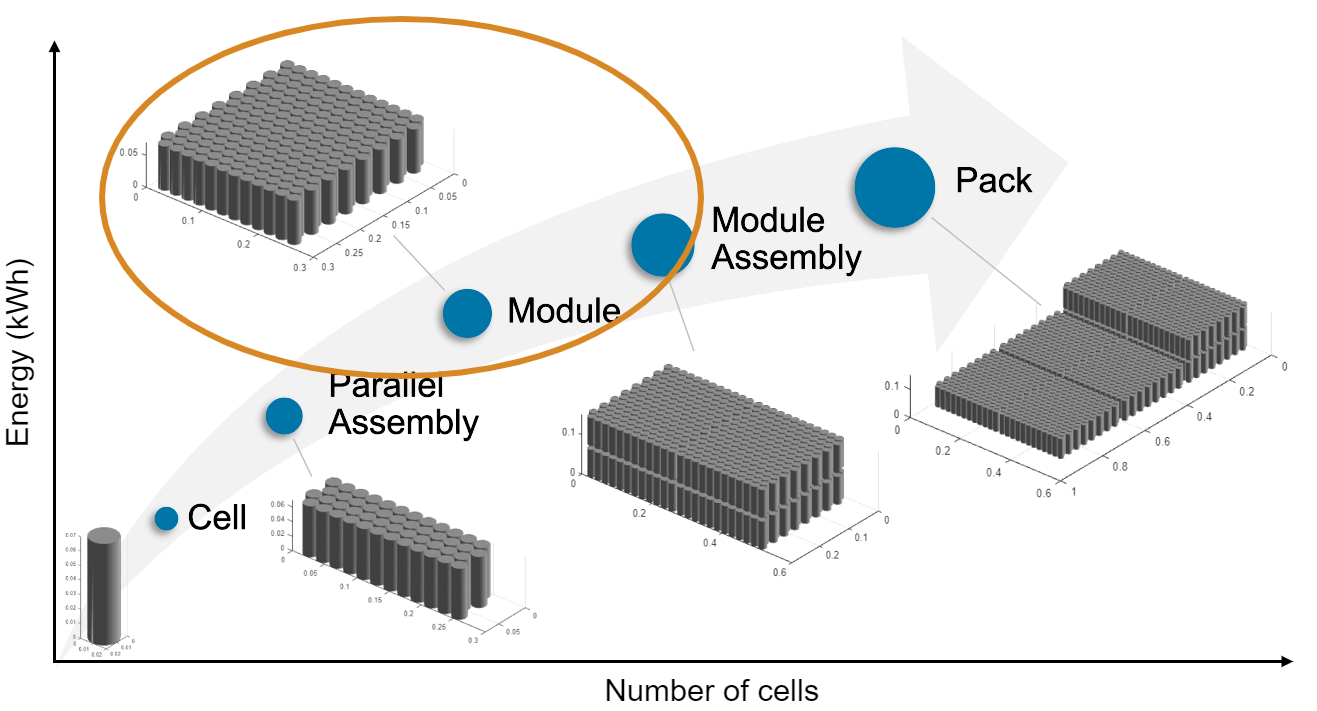

A battery module comprises multiple parallel assemblies. These parallel assemblies, in turn, comprise a number of battery cells connected electrically in parallel under a specific topological configuration or geometrical arrangement.

After you create your battery module object, the [buildBattery](docid:battery_ref#mw_09717e3d-8095-4fa5-a313-6bd9a9da8244) function creates a library in your working folder that contains a system model block of a battery module. You can use this system model as a reference in your simulations. The run-time parameters for these models, such as the battery cell impedance or the battery open-circuit voltage, are defined after the model creation and are therefore not covered by the Battery Pack Builder classes. To define the run-time parameters, you can either specify them in the block mask of the generated Simscape models or use the `MaskParameters` argument of the `buildBattery` function. 

## Create Battery `Module` Object in MATLAB

This section shows how to programmatically generate a battery `Module` object from the MATLAB® Command Window. 

### Create `Cell` Object

To create the battery `Module` object, first create a Cell object of cylindrical format. The [CylindricalGeometry](docid:battery_ref#mw_c5224532-2b73-4d0f-b268-6be8da8acd16) object allows you to define the cylindrical geometrical arrangement of the battery cell. To create the CylindricalGeometry object, use the [`batteryCylindricalGeometry`](docid:battery_ref#mw_63eab259-11c2-4148-bf3e-48db24d7acf1) function using the cell height as the first argument and the radius as the second argument.

cylindricalGeometry = batteryCylindricalGeometry(simscape.Value(0.07,"m"),...
    simscape.Value(0.0105,"m"));

For more information on the possible geometrical arrangements of a battery cell, see the [PouchGeometry](docid:battery_ref#mw_894c2f15-2ce2-4fc8-9a3b-a9ff19c4a182) and [PrismaticGeometry](docid:battery_ref#mw_ec08796b-482d-4e27-8ada-0dd1efd7a1af) documentation pages.

Now use this `CylindricalGeometry` object to create a cylindrical battery cell.

cylindricalCell = batteryCell(cylindricalGeometry)

cylindricalCell =   Cell with properties:

            Geometry: [1×1 simscape.battery.builder.CylindricalGeometry]
    CellModelOptions: [1×1 simscape.battery.builder.CellModelBlock]
                Mass: 0.1000 (kg)
            Capacity: 5 (A*hr)
              Energy: 50 (W*hr)

Show all properties


For more information, see the [Cell](docid:battery_ref#mw_2d026fef-ba0c-4c1a-92e1-11623b831691) documentation page.

The Cell object allows you to simulate the thermal effects of the battery cell by using a simple 1-D model. To simulate the thermal effects of the battery cell, in the `BlockParameters` property of the `CellModelOptions` property of the `Cell` object, set the `thermal_port` parameter to `"model"`.

cylindricalCell.CellModelOptions.BlockParameters.thermal_port = "model";

### Create `ParallelAssembly` Object

A battery parallel assembly comprises multiple battery cells connected electrically in parallel under a specific topological configuration or geometrical arrangement. In this example, you create a parallel assembly of four cylindrical cells stacked in a square topology over four rows. 

To create the `ParallelAssembly` object, use the [`batteryParallelAssembly`](docid:battery_ref#mw_4dcd3a36-27f9-4286-afbe-bfabd21f1b76) function. Define the `Cell` object as the first argument and the number of cells in parallel as the second argument. To specify the additional parallel assembly properties, use the name-value arguments `Rows` and `Topology`.

parallelAssembly = batteryParallelAssembly(cylindricalCell,...
    4, ...
    Rows=4, ...
    Topology="Square", ...
    ModelResolution="Detailed");

For more information, see the [ParallelAssembly](docid:battery_ref#mw_a3e68eac-4afa-4391-b3ee-d464d818e28d) documentation page.

### Create `Module` Object

You now have all the foundational elements to create your battery module. A battery module comprises multiple parallel assemblies connected in series. In this example, you create a battery module of 13 parallel assemblies with an intergap between each assembly of 0.005 meters. You also define the model resolution of the module and add an ambient thermal boundary condition.

To create the `Module` object, use the [`batteryModule`](docid:battery_ref#mw_e3820991-1488-40bc-8d4d-e99c91843474) function. Define the `ParallelAssembly` object as the first argument and the number of parallel assemblies in series as the second argument. To specify the additional module properties use the name-value arguments `InterParallelAssemblyGap`, `ModelResolution`, and `AmbientThermalPath`

module = batteryModule(parallelAssembly,...
    13, ...
    InterParallelAssemblyGap=simscape.Value(0.005,"m"), ...
    ModelResolution="Detailed", ...
    AmbientThermalPath="CellBasedThermalResistance")

module =   Module with properties:

    NumSeriesAssemblies: 13
       ParallelAssembly: [1×1 simscape.battery.builder.ParallelAssembly]
        ModelResolution: "Detailed"
         SeriesGrouping: [1 1 1 1 1 1 1 1 1 1 1 1 1]
       ParallelGrouping: [4 4 4 4 4 4 4 4 4 4 4 4 4]

Show all properties


For more information, see the [Module](docid:battery_ref#mw_7667d6f8-0894-4334-b1b0-07b10449021a) documentation page.

## Visualize Battery Module and Check Model Resolution

To obtain the number of Simscape Battery(Table-based) blocks used for the pack simulation, use the `NumModels` property of your `Module` object.

disp(module.NumModels);

    52



To visualize the battery module before you build the system model and to view its model resolution, use the `BatteryChart` object. Create the figure where you want to visualize your battery module.

f = figure(Color="w",Position=[0 0 1000 500]);
tl = tiledlayout(1,2,Parent=f,TileSpacing="Compact",Padding="tight");

Then use the `batteryChart` function to visualize the battery module. To view the model resolution of the module, define the name-value argument `SimulationStrategyVisible` as `"On"`.

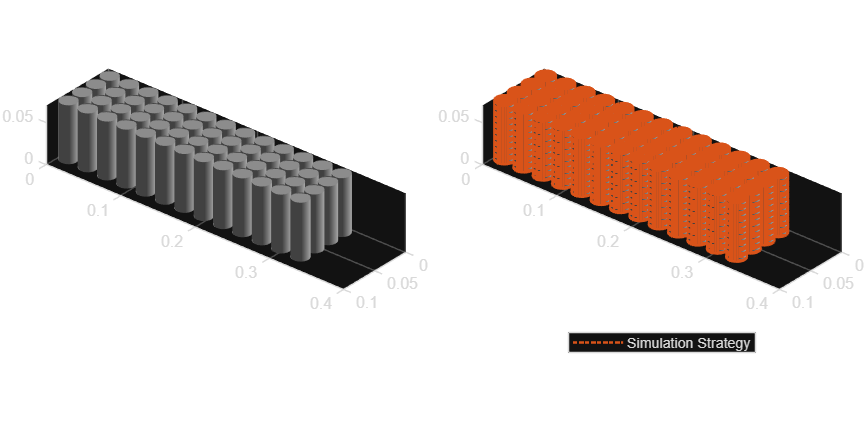

nexttile(tl)
moduleChart1 = batteryChart(tl,module);
nexttile(tl)
moduleChart2 = batteryChart(tl,module,SimulationStrategyVisible="On");

For more information, see the [BatteryChart](docid:battery_ref#mw_dbe5f15f-3424-47d4-8766-393cc212cfa7) documentation page.

## Build Simscape Model for the Battery Module Object

After you have created your battery objects, you need to convert them into Simscape models to be able to use them in block diagrams. You can then use these models as reference for your system integration and requirement evaluation, cooling system design, control strategy development, hardware-in-the-loop, and many more applications.

To create a library that contains the Simscape Battery model of the `Module` object in this example, use the `buildBattery` function.

buildBattery(module,LibraryName="moduleLibrary",Verbose="off");

This function creates a library named `moduleLibrary_lib` in your working directory. This library contains the Simscape models of your M`odule` and `ParallelAssembly` objects. 

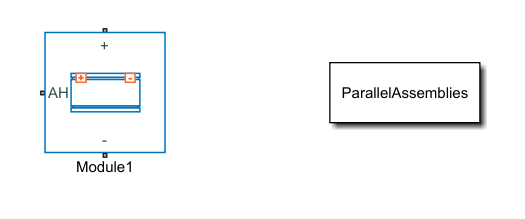

To build a battery pack model, see the [Build a Simple Model of a Battery Pack in MATLAB and Simscape](docid:battery_ug#example-batt_build_battery_pack) example.

## Explore Battery Module and Build Model in Battery Builder App 

In this example, you programmatically created the battery module and all its subcomponents by calling the relevant objects and functions in the MATLAB Command Window. Alternatively, if you prefer a more interactive and visual approach, you can use the [Battery Builder](docid:battery_ref#mw_df55e9aa-c1ab-4c71-b0e0-7d755cbe0b59) app. Using this app, you can interactively import existing battery objects or build them from scratch, explore and edit properties, and view the battery hierarchy and 3-D visualization. You can then build the Simscape system model of your objects and use it as a reference in your simulations. You can also export the objects in your workspace. To learn how to use the Battery Builder app to generate battery objects and build Simscape models, see the [Get Started with Battery Builder App](docid:battery_ug#example-batt_get_started_battery_builder_app) example.

Explore the battery module that you created in this example. Open the Battery Builder app. On the Apps tab, under Simscape, click the Battery Builder icon. Alternatively, you can open the app from the command line:

Import the battery module object from the `moduleLibrary` MAT file. Under the **Battery Builder** tab, in the **Import** section of the toolstrip, click **Import**. Then click **Import from MAT-file **and load the `moduleLibrary` MAT file.

The Battery Builder app now comprises a `Module` object and each of its subcomponents.

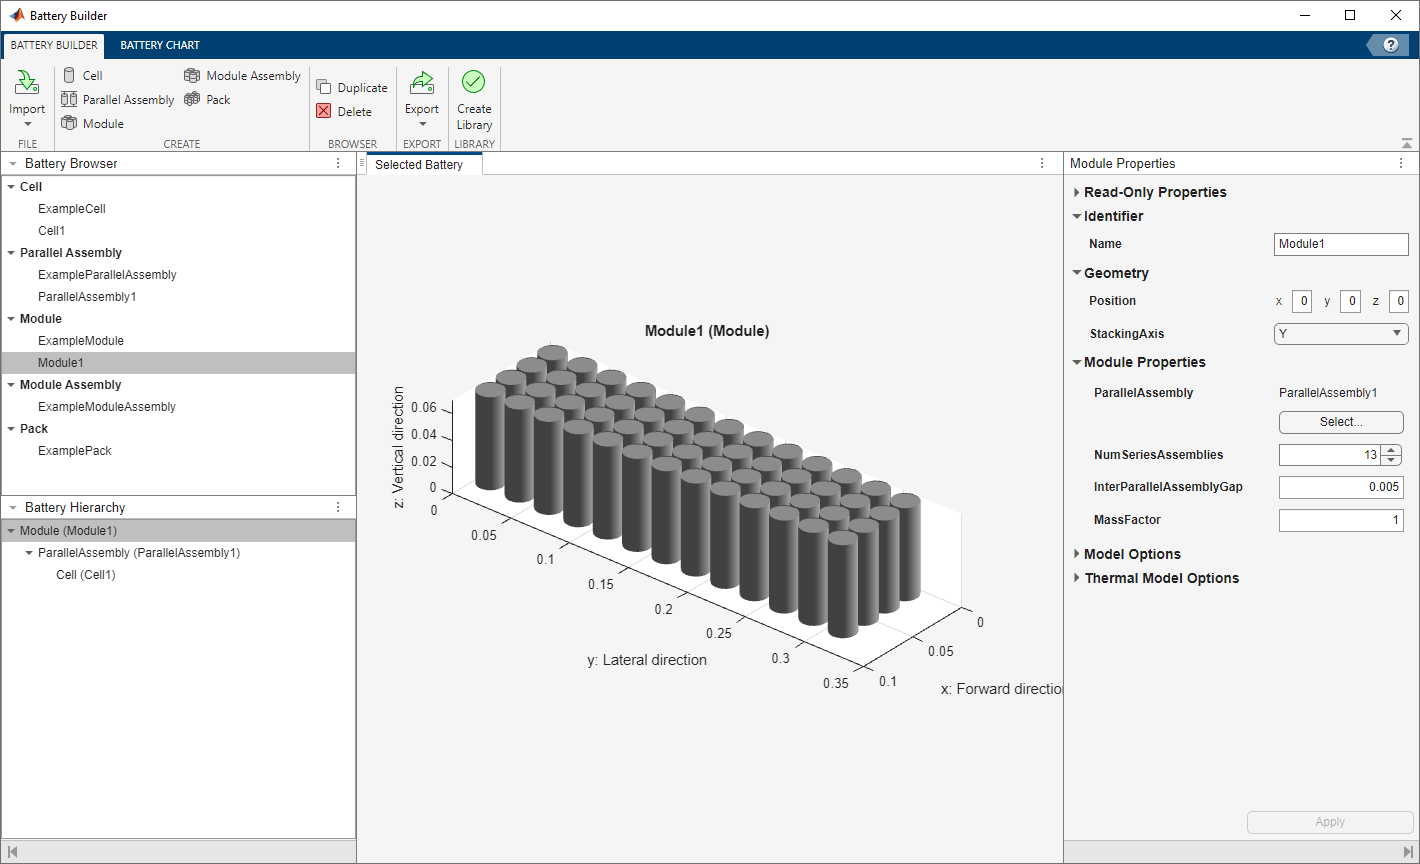

The **Battery Browser** panel on the left of the app contains all the battery objects in the current active session of the app. You can select an object, visualize it in the **Selected Battery** tab, check its hierarchy and child objects in the **Battery Hierarchy** panel, and edit its properties in the **Properties** panel on the right of the app.

You can edit properties of the plot under the **Battery Chart** tab, such as the axes labels, axes direction, title of the plot, and lights. You can also check the current simulation strategy and model resolution of the selected battery object. To visualize the simulation strategy in the plot, in the **Simulation Strategy** section of the toolstrip, check the **Visible** box.

Finally, if you modified your battery object and you want to create a library model of the updated M`odule` object, under the **Battery Builder** tab, in the **Library** section of the toolstrip, click **Create Library**. In the new window, specify the folder in which you want to save the library, the library name, and whether to use numeric values or variable names for the mask parameters and mask initial targets. 

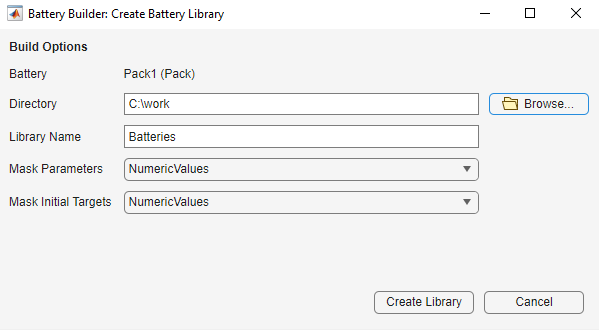

Click **Create Library** to generate the updated library model of your battery object in the specified folder. Open this model to access your battery objects as Simscape blocks that you can use as a starting point for architecture evaluation in early development stages, software and hardware development, system integration and requirement evaluation, cooling system design, control strategy development, hardware-in-the-loop, and many more applications.

*Copyright 2022 -2023 The MathWorks, Inc.*